函数用来计算多层薄膜系统的反射和透射系数，本函数是基于梁廷铨物理光学4.4节编写的，相比基于唐晋发的现代光学薄膜技术编写的TMM更便于理解些。

**输入**

- polarization：入射光偏振态，为char格式，‘p'表示p偏振，’s'表示s偏振

- lambda：入射波长，double格式，单位是nm

- theta0：入射角度，单位是°

- thickness：各层厚度，要求输入是一个一维向量，单位是nm

- refractive_ind：折射率，要求输入形式是n+ik，也可以通过sqrt（epsilon）的方式输入介电常数，要求介电常数的方式也是u+iv

**输出**

- r：反射系数，注意，反射系数的相位与基矢的选择有关，基矢一旦改变反射系数随之改变，但不影响反射率的大小

- t：透射系数

function [r,t] = TMM(polarization,lambda,theta0,thickness,refractive_ind)

    thickness = thickness/10^9; % 厚度化为国际单位制
    epsilon0 = 8.854187817*10^(-12);    % 真空介电常数
    mu0 = 4*pi*10^(-7); % 真空磁导率
    eta0 = sqrt(epsilon0/mu0);  % 自由空间光学导纳
    N = length(thickness);  % 层数
    M = eye(2); % 转移矩阵初始化
    lambda = lambda/10^9;   % 波长化为国际单位
    theta0 = theta0*pi/180;
    
    theta = asin(refractive_ind(1)*sin(theta0)./refractive_ind);    % 各层入射角
    delta = 2*pi/lambda*refractive_ind.*thickness.*cos(theta);  % 各层z方向光程
    eta = strcmp(polarization,'s')*eta0*refractive_ind.*cos(theta) + ...
            strcmp(polarization,'p')*eta0*refractive_ind./cos(theta);   % 各层有效光学导纳
        
    if N > 2    % 大于两层时用传输矩阵法      
        for ii = 2:(N-1)
            M_ii = [cos(delta(ii)) -1i*sin(delta(ii))/eta(ii);...
                -1i*sin(delta(ii))*eta(ii) cos(delta(ii))];
            M = M*M_ii;
        end
        A = M(1,1);
        B = M(1,2);
        C = M(2,1);
        D = M(2,2);
        etai = eta(1);  % 入射层有效光学导纳
        etao = eta(end);    % 出射层有效光学导纳
        r = (A*etai + B*etai*etao - C - D*etao)/(A*etai + B*etai*etao + C + D*etao)*...
            (-strcmp(polarization,'p') + strcmp(polarization,'s'));
        t = 2*etai/(A*etai + B*etai*etao + C + D*etao)*...
            (cos(theta(1))/cos(theta(end))*strcmp(polarization,'p') + ...
            strcmp(polarization,'s'));
    elseif N == 2       % 等于两层时用菲涅尔公式
        r = -sin(theta(1) - theta(2))/sin(theta(1) + theta(2))*strcmp(polarization,'s') + ...
            tan(theta(1) - theta(2))/tan(theta(1) + theta(2))*strcmp(polarization,'p');
        t = 2*sin(theta(2))*cos(theta(1))/sin(theta(1) + theta(2))*strcmp(polarization,'s') + ...
            2*sin(theta(2))*cos(theta(1))/(sin(theta(1) + theta(2))*cos(theta(1) - theta(2)))*strcmp(polarization,'p');
    end
    
end

**说明**

        1、半波损失

反射过程中有无半波损失的发生，应该以s偏振为参考。因为s偏振在反射前后基矢没有发生改变，即反射前后参照系是一致的，此时如果计算出来反射率是个负数，那么就说明反射过程中存在半波损失。那为什么p偏振不可以呢？因为习惯上，p偏振在反射前后基矢方向发生了改变，相位信息包含在方向里面，如果参照系发生了改变，那么就无从讨论相位的变化了。这里可以考虑一种极限情况，亦即当入射角度为0°的时候，此时s偏振和p偏振应该对应同一种情况。我们假设此时反射过程存在半波损失，那么s偏振的反射率应该是负数，而p偏振的反射率应该是正数，且|rs| = |`rp|，rs与rp的符号之所以不同，原因就在于基矢选择的不同。如下图：`

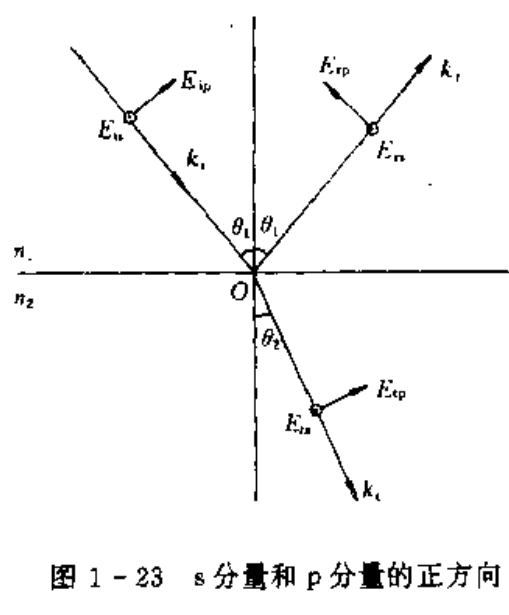

这种情况默认p偏振光在反射时伴随有参考方向的改变，即使有半波损失，rp也仍是正的，反倒是下图中的选择方式对应的rp的符号与rs相同，在垂直入射时rp=rs：

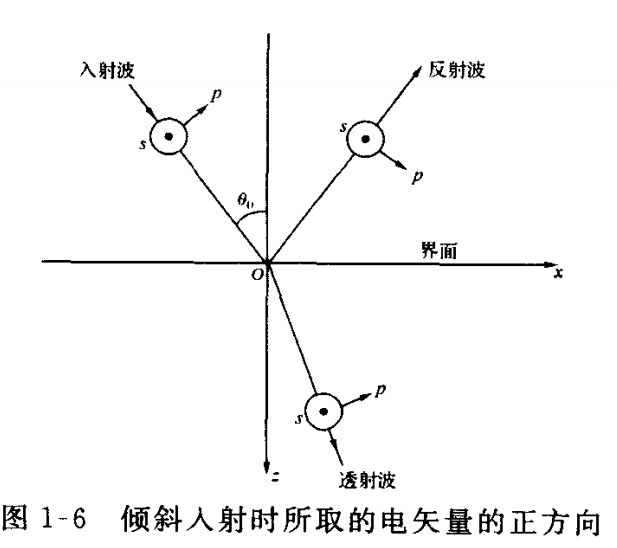

但这种基矢的选择毕竟是少数，主流情况下还是上一种选择，那么这时垂直入射时，如果有半波损失，则rs+rp=0。

此处code是根据梁铨廷的物理化学写的，该书的符号与第一种同。

        2、透射系数大于1

透射系数是可以大于1的，这并不违背能量守恒定律。透射系数是电场强度的比值，而能流大小则还需与折射率进行关联。即便电场强度很大，折射率较小时其能量也是偏小的：

（上面公式差了一个自由空间导纳，但结论是对的）

具体可以参考：[(17 封私信 / 60 条消息) 光密到光疏介质透射系数大于1吗? - 知乎 (zhihu.com)](https://www.zhihu.com/question/328648725)

        3、折射率

透射率（包括反射率）跟透射系数是不同的，且不仅仅是一个平方的差别，还需要考虑能流方向：

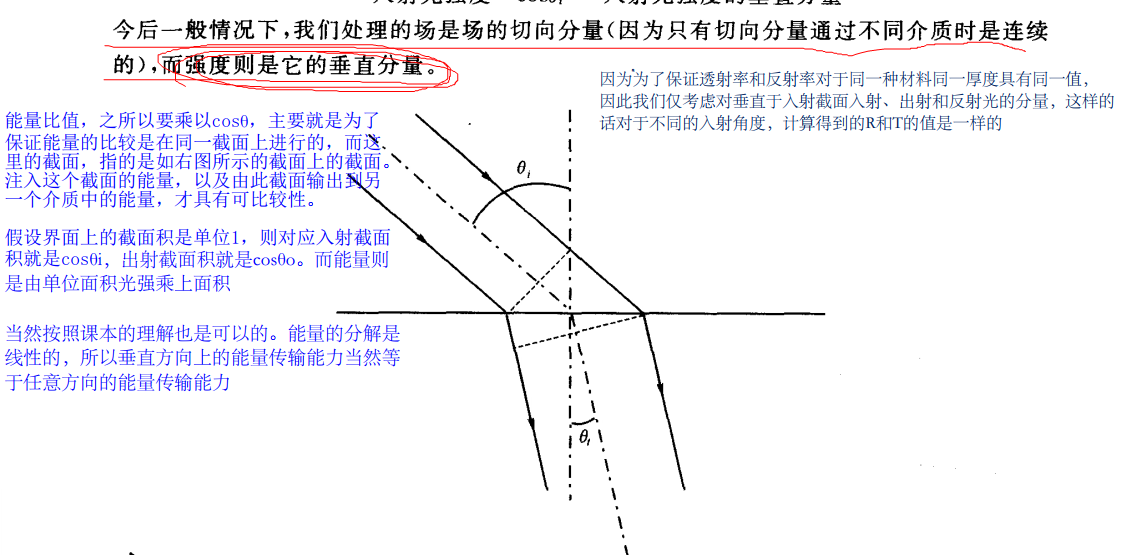

但如果只考虑透射之后电场振幅和相位的变化，则使用透射系数即可。

        4、p偏振对应的TMM推到

梁书只有s偏振的推导，p偏振的推到跟s偏振（梁书P142-P145）大同小异，但在结论上略有差别：